# **Introductory script illustrating how to compute treeshrew cone mosaic excitation responses to an ISETBio scene.**

*This tutorial generates an ISETBio scene representing a Gabor stimulus as realized on a particular display, passes this scene through the default  treeshrew optics, and computes cone mosaic excitation responses. The simulation parameters here are appropriate for treeshrew experiments. *

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

- `t_coneIsomerizationsFromSceneOnDisplay.mlx ` (parameters specific to the human visual system)

- t_opticsTreeShrew.mlx (expore various optics params)

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Create a presentation display and a low-frequency Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

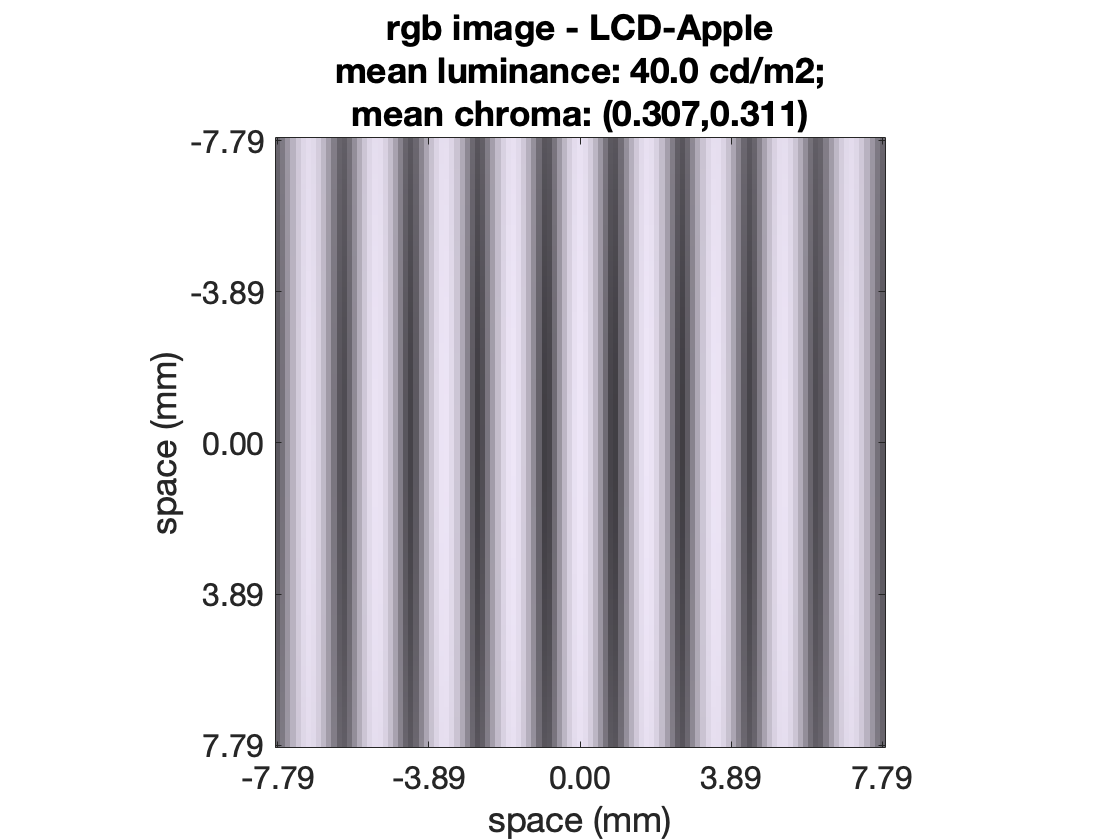

%% Create presentation display and place it 5 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 30/100);

%% parameter struct for a low spatial frequency Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 3.0, ... % 3.0 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 0, ...                     % spatial phase degrees, 0 = cos, 90 = sin
    'sizeDegs', 3, ...                     % 14 x 14 size
    'sigmaDegs', 1*3, ...                   % sigma of Gaussian envelope
    'contrast', 0.9,...                     % 0.9 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );


% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 5);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene, ...
    'displayContrastProfiles', ~true, ...
    'displayRadianceMaps', false);

# **Step 2.** Compute the optical image using the default TreeShrew optics

We employ the default treeshrew optics which are based on a Gaussian PSF. The scene is passed through the optics model to compute the retinal image.

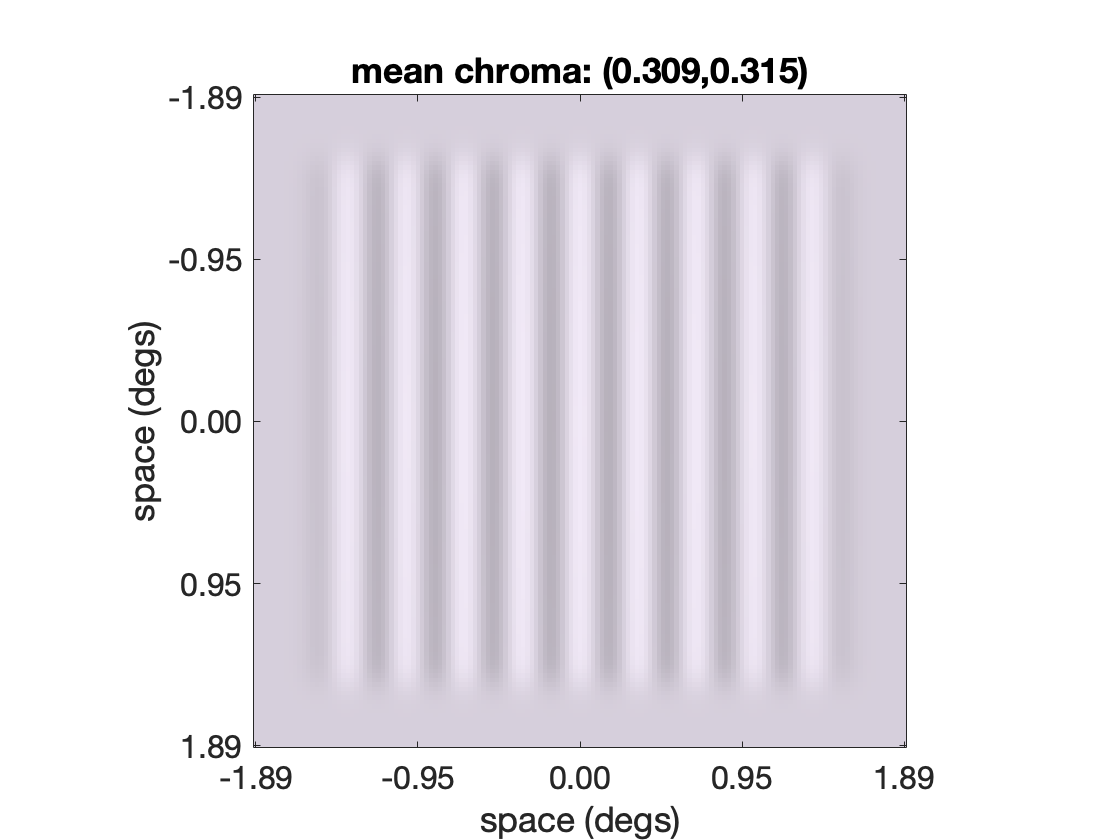

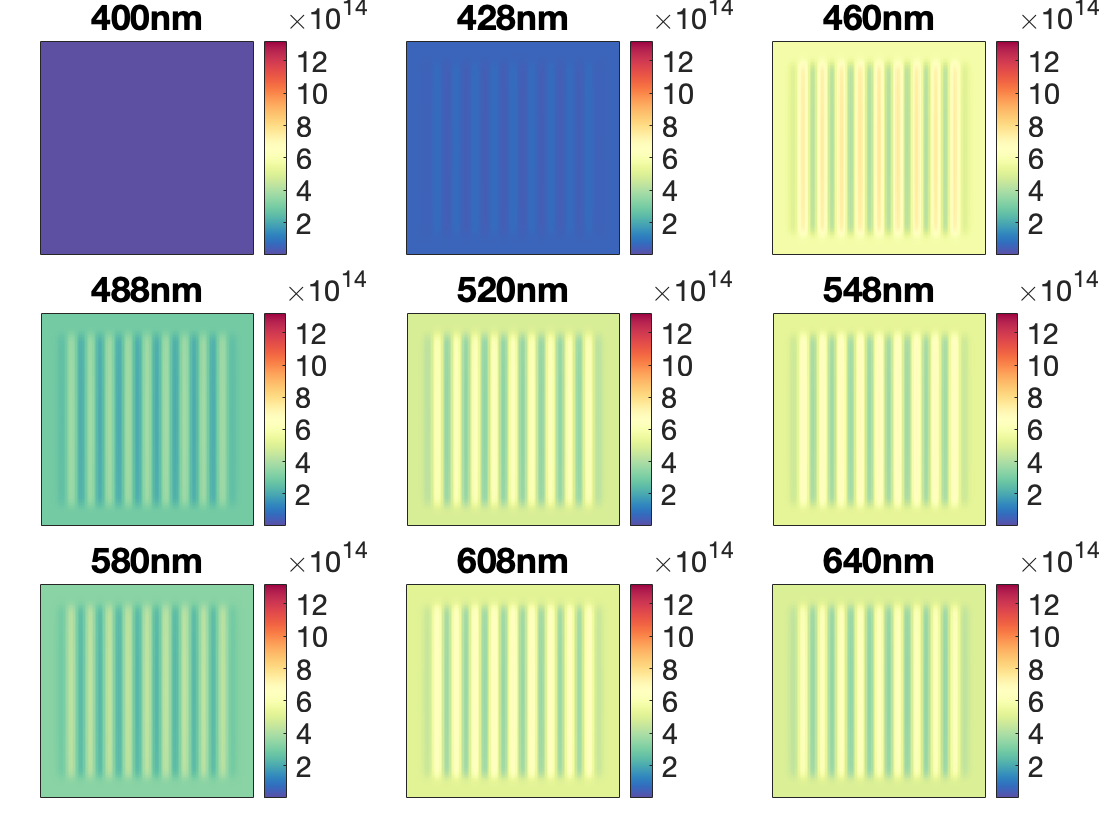

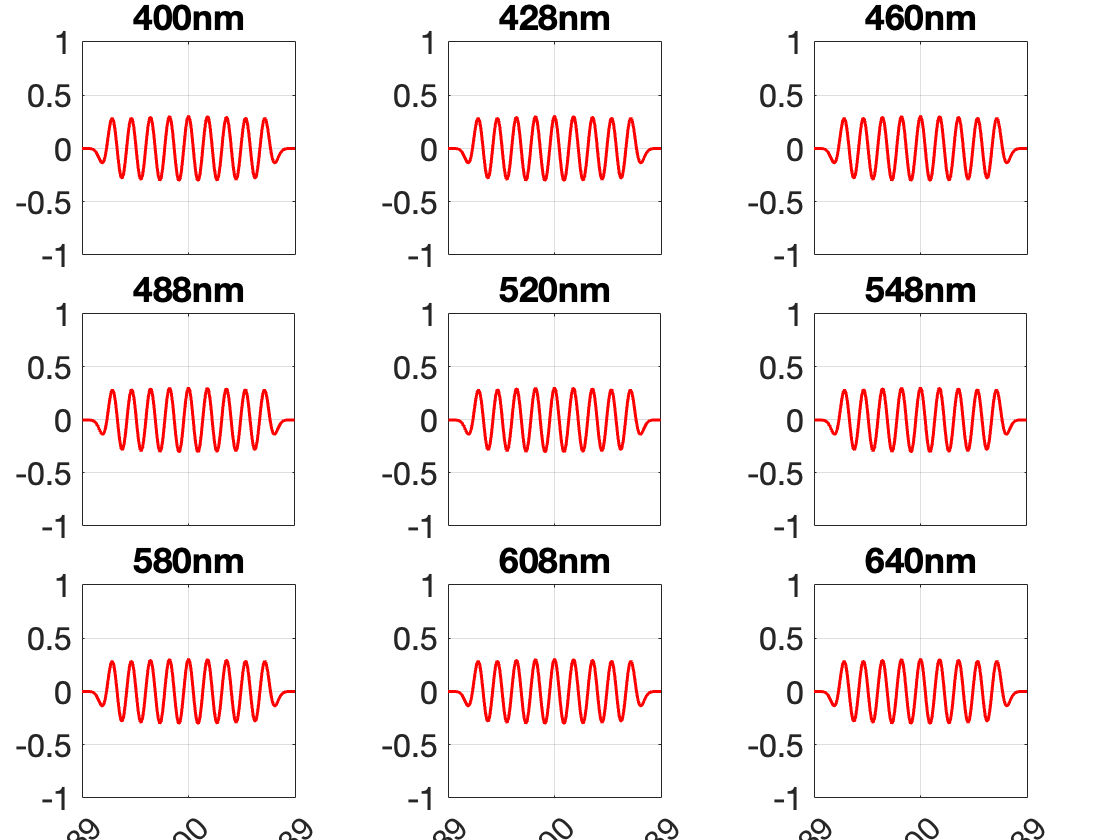

%% Generate default treeshrew optics
theOI = oiTreeShrewCreate();

%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI, 'displayRetinalContrastProfiles', true);

# **Step 3.** Generate the default TreeShrew cone mosaic

Generate and visualize the default three shrew cone mosaic

% Generate default treeshrew cone mosaic with a 5 msec integration time
theConeMosaic = coneMosaicTreeShrewCreate(...
    theOI.optics.micronsPerDegree, ...
    'fovDegs', stimParams.sizeDegs*[1 1], ...
    'integrationTime', 1/1000);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 784
Scones after making an S-cone free central patch: 784 (added Lcones:0, added Mcones:0)
Scones after pass 1: 465 (added Lcones:420, added Mcones:0)
Scones after pass 2: 272 (added Lcones:254, added Mcones:0)
Scones after pass 3: 158 (added Lcones:149, added Mcones:0)
Scones after pass 4: 95 (added Lcones:75, added Mcones:0)
Scones after pass 5: 80 (added Lcones:16, added Mcones:0)
Scones after pass 6: 79 (added Lcones:1, added Mcones:0)
Scones after pass 7: 79 (added Lcones:0, added Mcones:0)


theConeMosaic.displayInfo();


Mosaic info:
                                      Size (microns): 228.0 (w) x 228.0 (h)
                                           FOV (deg): 3.00 (w) x 3.00 (h)
                                   Retinal coverages: 0.840 (aperture) x 0.897 (geometric)
                              Grid resampling factor: 3
                   Cone geometric aperture (microns): 5.49 (w) x 5.49 (h), diameter: 6.20
             Cone light colleting aperture (microns): 5.32 (w) x 5.32 (h), diameter: 6.00
                     Cone geometric area (microns^2): 30.1907 
               Cone light colleting area (microns^2): 28.2743
                                    Rectangular grid: 29 cols x 29 rows
                                      Resampled grid: 342 cols x 342 rows
                                         Total cones: 116964
                                        Active cones: 1569
                                            L- cones: 1490 (94.965%)
                                            M- co

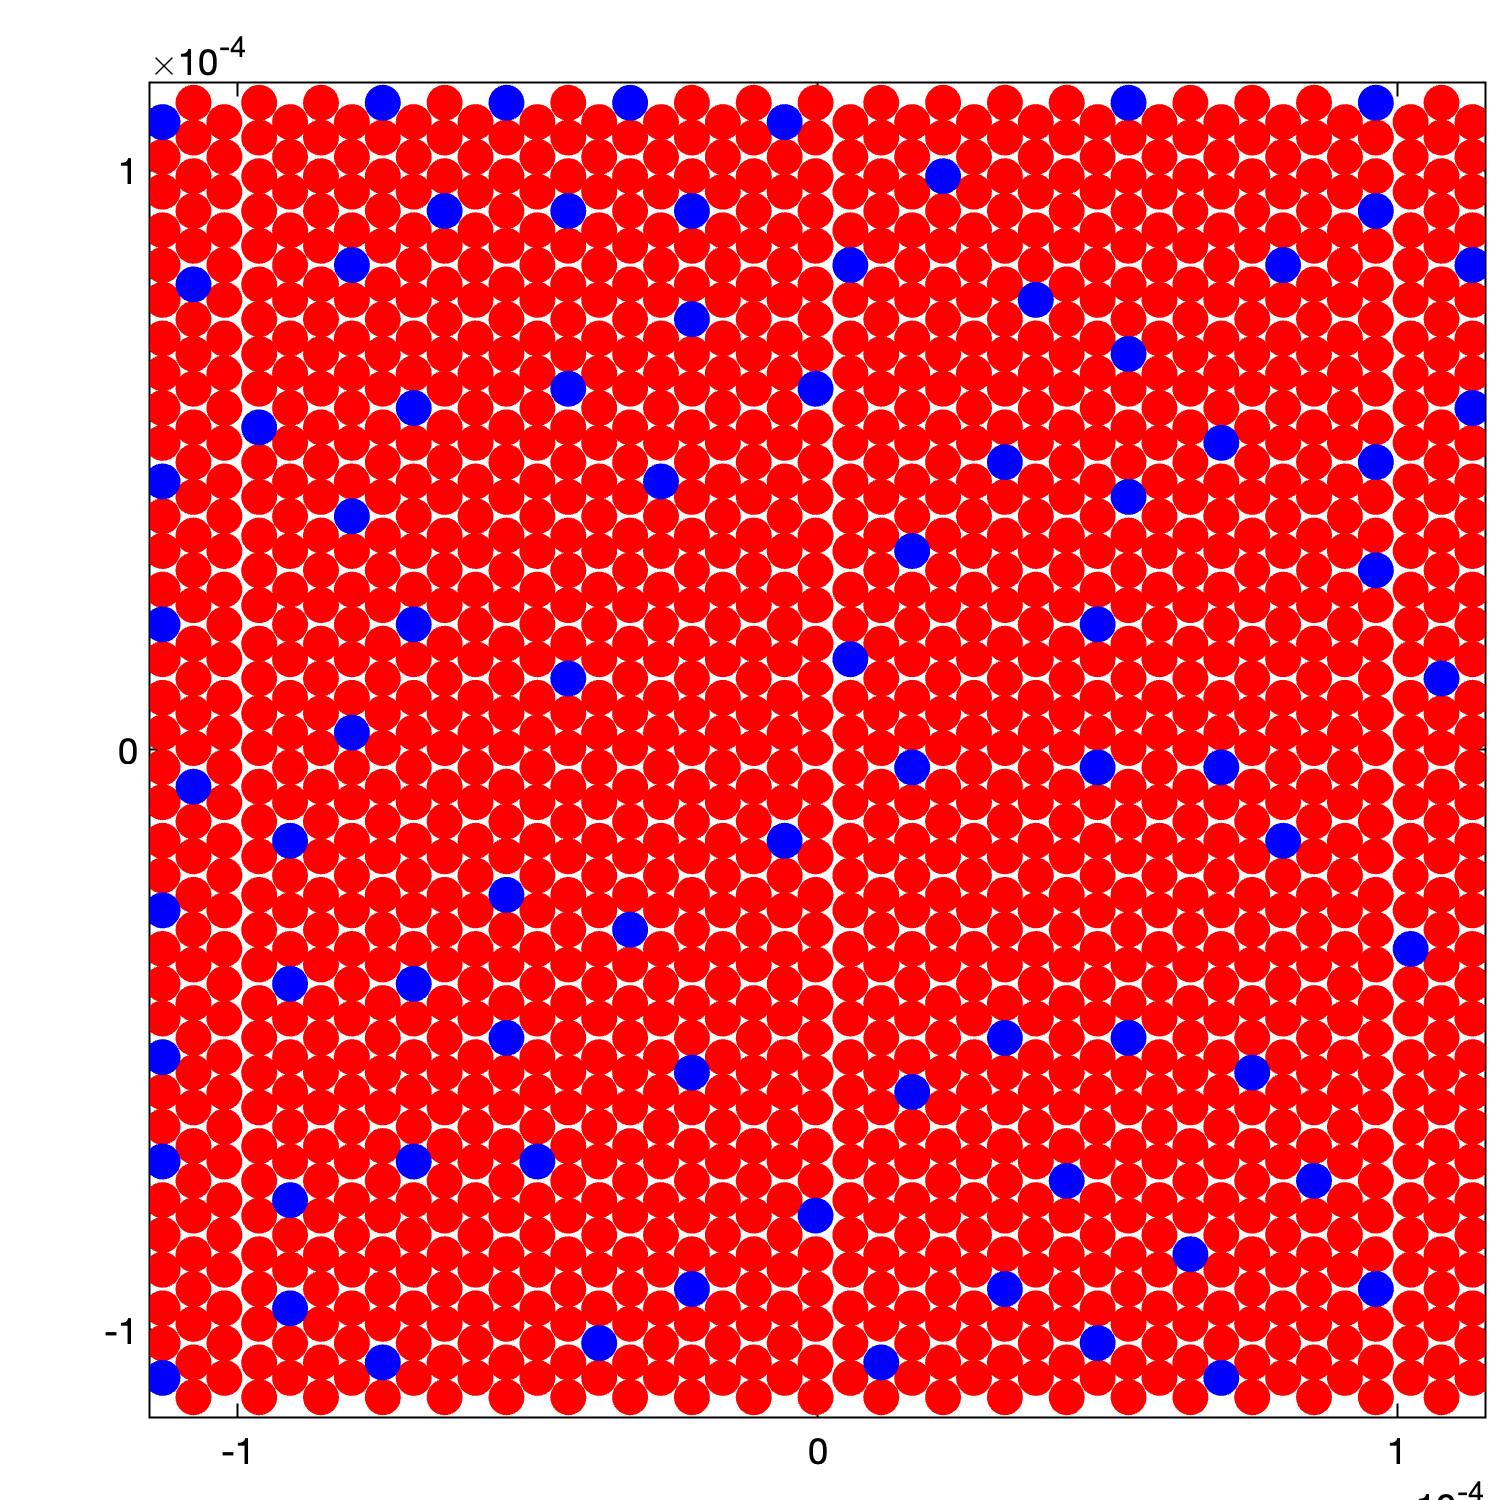

theConeMosaic.visualizeGrid('backgroundColor', [1 1 1], 'generateNewFigure', true); 

# **Step 4.** Generate cone excitation responses to the optical image

### Step 4.1 Generate responses

Here we are generating some cone excitation response instances

nTrialsNum = 10;
emPath = zeros(nTrialsNum, 1, 2);
% Compute mosaic excitation responses
coneExcitations = theConeMosaic.compute(theOI, 'emPath', emPath);
size(coneExcitations)

ans =     10   342   342


### Step 4.2 Visualize results. 

We are visualizing the cone mosaic on the left, along with the first two response instances. All computed responses instances for cones located along the horizontal meridian are visualized on the bottom plot.

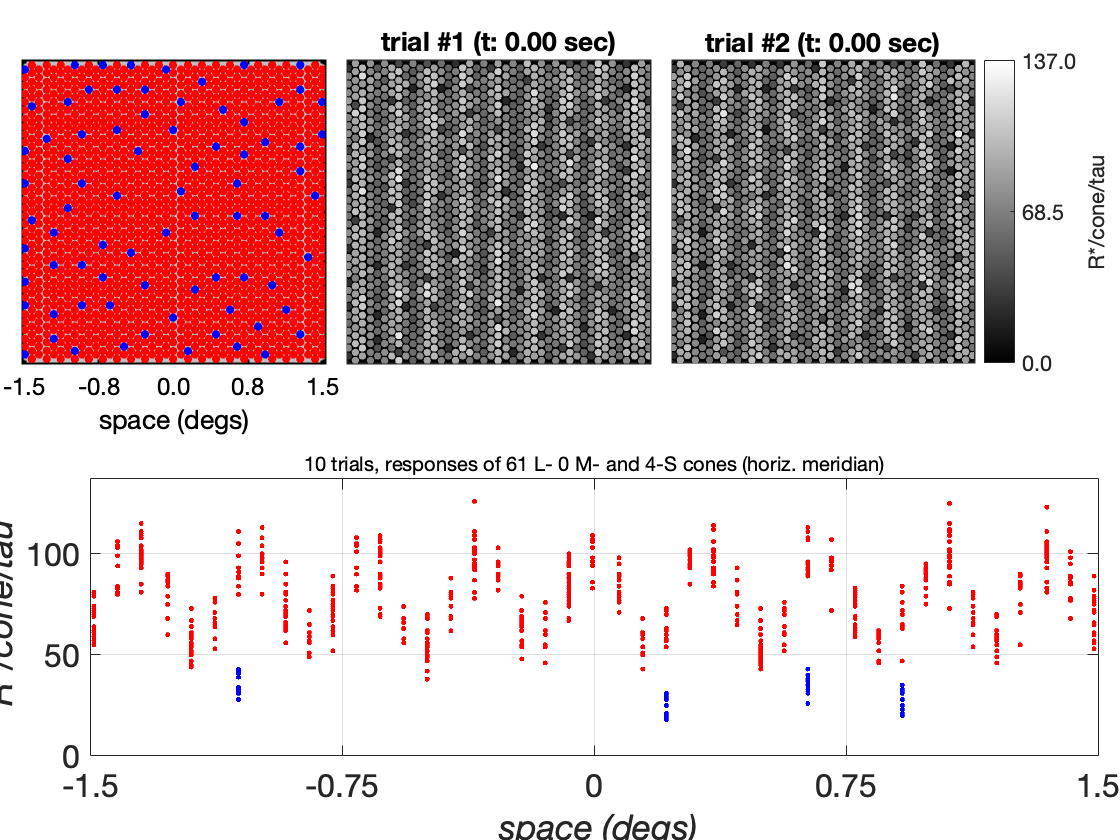

%% Visualize cone mosaic and its cone excitation responses
visualizeConeMosaicResponses(theConeMosaic, coneExcitations, 'R*/cone/tau');